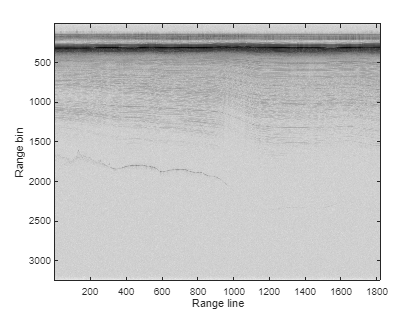

clear all
close all
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20240105_02\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20240105_02\

load Data_img_01_20240105_02_005.mat
load Data_20240105_02_005.mat

% load echogram!
echo = load('Data_img_01_20240105_02_005.mat','Data','Time','GPS_time');
h_fig = figure;
h_axes = axes;
imagesc(lp(echo.Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);
hold on


layer = load('C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layerData\20240105_02\Data_20240105_02_005.mat','GPS_time','layerData');
Surface = interp1(echo.Time,1:length(echo.Time),layer.layerData{1}.value{2}.data);
Bottom = interp1(echo.Time,1:length(echo.Time),layer.layerData{2}.value{2}.data);
Surface = interp1(layer.GPS_time,Surface,echo.GPS_time);
Bottom = interp1(layer.GPS_time,Bottom,echo.GPS_time);
% 
% % plot surface/bottom lines
% hold(h_axes,'on');
% plot(Surface,'m--','parent',h_axes);
% plot(Bottom,'r--','parent',h_axes);
% hold off

% power = calibrateBrightness(20240105, 02, 005);
% depth = twtt2Depth(twtt, 1.77); % rwo 1 = surface, row 2 = bottom variables

bottomIndex = round(Bottom); % row indicies

% odd number that covers range of indices near bottom


pulledPoints = zeros(1, size(Data,2));

for i = 1:length(pulledPoints)
    pulledPoints(i) = Data(bottomIndex(i), i);

end 


% range = 5
% pulledPointsRange = zeros(5, length(pulledPoints))
% 
% for i = length(pulledPoints)
%     idx = bottomIndex(i);
%     range = (idx - range):(idx + range);
% 
%     pulledPointsRange = [pulledPointsRange; range];
% end 

pulledPointsRange = [bottomIndex+2 ; bottomIndex+1 ; bottomIndex ; bottomIndex-1 ; bottomIndex-2];
HELP = zeros(1819, 11);

for i = 1:length(pulledPoints)
    for j = -5:5 % if you change this variabe change the HELP(i, j+3) so j+x = 1 (index is positive)
        % I'm bad at coding don't come at me :')
    HELP(i,j+6) = Data(bottomIndex(i)+j, i);
    end 
end 

averageBrightness = mean(HELP, 2)'; % 10 bins
averageBrightness2 = mean(HELP(:, (4:8)), 2)'; % 5 bins


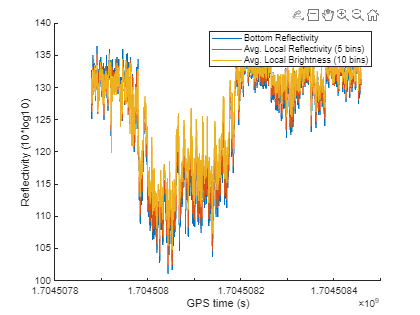


% graph the bottom reflectivity & local reflectivity (stacking graph)
close all
hold on 
plot(GPS_time, abs(10*log10(pulledPoints)))
    xlabel('GPS time (s)')
    ylabel('Reflectivity (10*log10)')

plot(GPS_time, abs(10*log10(averageBrightness2)))
plot(GPS_time, abs(10*log10(averageBrightness)))
    legend('Bottom Reflectivity', 'Avg. Local Reflectivity (5 bins)', 'Avg. Local Brightness (10 bins)')

    % plot layers above and below (NOT AVERAGE) (INDIVIDUAL LAYERS)
    % HELP is centered at 6
    hold off

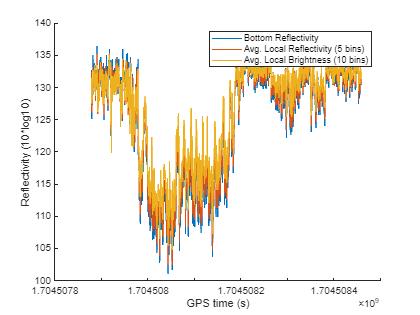

% plot(GPS_time, abs(10*log10(HELP(:, (5:7)))), ':')
colororder('gem');

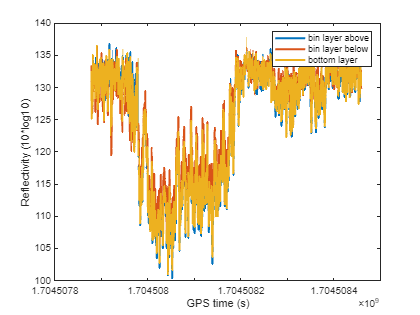

plot(GPS_time, abs(10*log10(HELP(:,5))), '-', 'LineWidth', 2) % above
    hold on
plot(GPS_time, abs(10*log10(HELP(:,7))), '-', 'LineWidth', 2) % below
plot(GPS_time, abs(10*log10(HELP(:,6))), '-', 'LineWidth', 2) % bottom layer

    xlabel('GPS time (s)')
    ylabel('Reflectivity (10*log10)')
    legend('bin layer above', 'bin layer below', 'bottom layer')
hold off

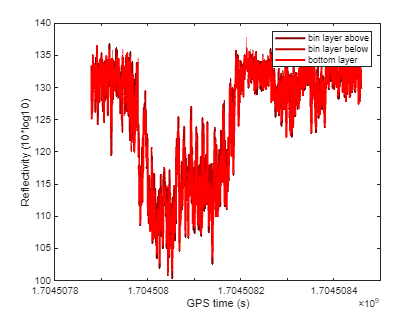

hold off
% make the colors make sense. I think.
colorarray = ...
   [.5 0 0
    .75 0 0 % redder above
    1 0 0
    0 0 0 % bottom = black
    0 0 1
    0 0 .75 % bluer below
    0 0 .5];
colororder(colorarray); % sets colors to work on plot

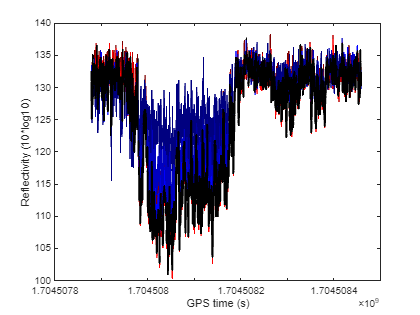


plot(GPS_time, abs(10*log10(HELP(:, (3:9)))),'-')
hold on
plot(GPS_time, abs(10*log10(HELP(:,6))), 'color', 'k', 'LineWidth', 2) % bottom layer
    xlabel('GPS time (s)')
    ylabel('Reflectivity (10*log10)')
% 3 4 5 6 7 8 9 
hold off

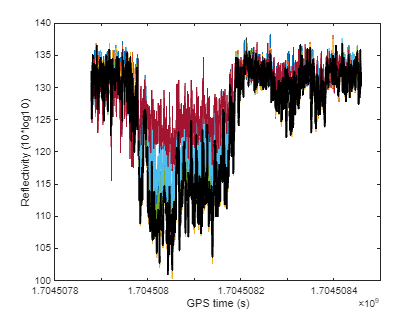

colororder('gem')
    % Compare reflectivity w/ averages & different bin sizes
tiledlayout(3, 1)

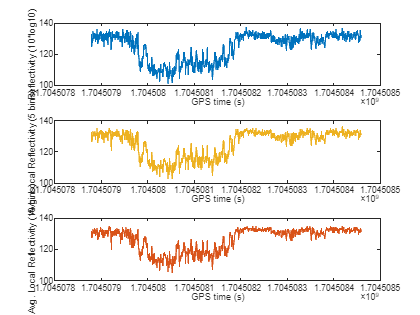


nexttile
plot(GPS_time, abs(10*log10(pulledPoints)))
    xlabel('GPS time (s)')
    ylabel('Reflectivity (10*log10)')

nexttile
plot(GPS_time, abs(10*log10(averageBrightness2)), 'color','#EDB120')
    xlabel('GPS time (s)')
    ylabel('Avg. Local Reflectivity (5 bins)')

nexttile
plot(GPS_time, abs(10*log10(averageBrightness)), 'color','#D95319')
    xlabel('GPS time (s)')
    ylabel('Avg. Local Reflectivity (10 bins)')